**Task 4.1**			

Estimate a homography matrix between a pair of images from **HG**. 					

a) Show the keypoints and their correspondences projected from the other image. 				

**Task 4.2**				

 Estimate fundamental matrix between a pair of images from **FD**. 			

a) Show the keypoints and their corresponding epipolar lines in the other image.

b) Show epipoles, vanishing points and horizon in your images. 

boxImage = imread('DSC_0597.png');
sceneImage = imread('DSC_0600.png');
boxImage = rgb2gray(boxImage);
sceneImage = rgb2gray(sceneImage);

boxPoints = detectSIFTFeatures(boxImage);
scenePoints = detectSIFTFeatures(sceneImage);

% Extract feature descriptors at the interest points in both images.
[boxFeatures, boxPoints] = extractFeatures((boxImage), (boxPoints));
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

% Match the features using their descriptors.
boxPairs = matchFeatures(boxFeatures, sceneFeatures);

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);

showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, matchedScenePoints);


% Estimate Fundamental Matrix:
[fLMedS,inliers] = estimateFundamentalMatrix(matchedBoxPoints,...
    matchedScenePoints,'NumTrials',4000)

figure; 
% subplot(121);
imshow(boxImage); 
title('Inliers and Epipolar Lines in First Image'); hold on;
plot(matchedBoxPoints(inliers,1),matchedBoxPoints(inliers,2),'go')



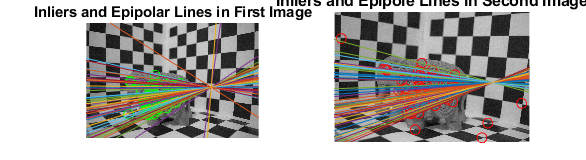

clear
I1 = rgb2gray(imread('DSC_0597.png'));
I2 = rgb2gray(imread('DSC_0600.png'));
points1 = detectSURFFeatures(I1);
points2 = detectSURFFeatures(I2);
[features1, valid_points1] = extractFeatures(I1, points1);
[features2, valid_points2] = extractFeatures(I2, points2);
%Use the sum of absolute differences (SAD) metric to determine indices of matching features.
indexPairs = matchFeatures(features1, features2);
%Retrieve locations of matched points for each image
matched_points1 = valid_points1(indexPairs(:, 1), :);
matched_points2 = valid_points2(indexPairs(:, 2), :);


[fLMedS, inliers] = estimateFundamentalMatrix(matched_points1, matched_points2, 'NumTrials', 4000);
%%%%conversion of matched_points1 to matrix
sS = 100;
xm1 = matched_points1.selectStrongest(sS);
m1 = zeros(sS,2,'double');
newInliners = logical(sS);
wielCP = size(matched_points1);
wielCP = wielCP(1,1);
for y = 1:sS
  am1 = xm1(y);
  m1(y,1) = am1.Location(1,1);
  m1(y,2) = am1.Location(1,2);
    for z = 1 : wielCP
        b = matched_points1(z);
        temp_a1 = am1.Location(1,1);
        temp_a2 = am1.Location(1,2);
        temp_b1 = b.Location(1,1);
        temp_b2 = b.Location(1,2);
        if temp_a1 == temp_b1 && temp_a2 == temp_b2
            newInliners(y) = inliers(z);
        end
    end
end
newInliners = newInliners';
%%%%conversion of matched_points2 to matrix
xm2 = matched_points2.selectStrongest(sS);
m2 = zeros(sS,2,'double');
for y = 1:sS
  am2 = xm2(y);
  m2(y,1) = am2.Location(1,1);
  m2(y,2) = am2.Location(1,2); 
end
%%%%%%%%
figure;
subplot(121); imshow(I1);
title('Inliers and Epipolar Lines in First Image'); hold on;
plot(m1(newInliners,1), m1(newInliners,2), 'go')
% Compute the epipolar lines in the first image.
epiLines = epipolarLine(fLMedS', m2(newInliners, :));
% Compute the intersection points of the lines and the image border.
pts = lineToBorderPoints(epiLines, size(I1));
% Show the epipolar lines in the first image
line(pts(:, [1,3])', pts(:, [2,4])');
% Show the inliers in the second image.
subplot(122); imshow(I2); title('Inliers and Epipole Lines in Second Image'); hold on;
plot(m2(newInliners,1), m2(newInliners,2), 'ro')
% Compute and show the epipolar lines in the second image.
epiLines = epipolarLine(fLMedS, m1(newInliners, :));
pts = lineToBorderPoints(epiLines, size(I2));
line(pts(:, [1,3])', pts(:, [2,4])');
truesize;

**Task 4.3**		

Find out how many outliers the estimation method tolerates 				